# Object Detection Using YOLO v4 Deep Learning

This example shows how to detect objects in images using you only look once version 4 (YOLO v4) deep learning network. In this example, you will

- Configure a dataset for training, validation, and testing of YOLO v4 object detection network. You will also perform data augmentation on the training dataset to improve the network efficiency.

- Compute anchor boxes from the training data to use for training the YOLO v4 object detection network.

- Create a YOLO v4 object detector by using the `yolov4ObjectDetector` function and train the detector using `trainYOLOv4ObjectDetector` function.

This example also provides a pretrained YOLO v4 object detector to use for detecting vehicles in an image. The pretrained network uses tiny-yolov4-coco as the backbone network and is trained on a vehicle dataset. For information about YOLO v4 object detection network, see [Getting Started with YOLO v4](docid:vision_ug#mw_09b91dd4-f3cc-44fc-a420-ef5b7b940cb4).

## Load Dataset

This example uses a small vehicle dataset that contains 295 images. Many of these images come from the Caltech Cars 1999 and 2001 datasets, available at the Caltech Computational Vision website created by Pietro Perona and used with permission. Each image contain one or two labeled instances of a vehicle. A small dataset is useful for exploring the YOLO v4 training procedure, but in practice, more labeled images are needed to train a robust detector. 

Unzip the vehicle images and load the vehicle ground truth data.

imageDir = 'images/images';
annotationDir = 'annotation/annotation/YOLO-format';

% Comprobar si el archivo 'human_dataset.mat' ya existe
if isfile('human_dataset.mat')
    % Si el archivo existe, cargar los datos
    data2 = load('human_dataset.mat');
    humanDataset = data2.humanDataset;
else
    % Si no existe, se crea el archivo
    
    % Obtener la lista de archivos de imágenes
    imageFiles = dir(fullfile(imageDir, '*.jpg'));
    numImages = length(imageFiles);

    % Inicializar la tabla humanDataset
    humanDataset = table('Size', [numImages, 2], ...
        'VariableTypes', {'string', 'cell'}, ...
        'VariableNames', {'imageFilename', 'annotations'});

    % Iterar sobre las imágenes y cargar las anotaciones
    for i = 1:numImages
        % Obtener el nombre del archivo de imagen
        imageFilename = fullfile(imageDir, imageFiles(i).name);

        % Leer la imagen usando imread
        img = imread(imageFilename);

        % Obtener las dimensiones de la imagen directamente
        [img_height, img_width, ~] = size(img);

        % Obtener el nombre del archivo de anotación correspondiente
        [~, imageName, ~] = fileparts(imageFiles(i).name);
        annotationFile = fullfile(annotationDir, [imageName '.txt']);

        % Leer las anotaciones en formato YOLO
        if isfile(annotationFile)
            % Leer anotaciones del archivo
            yoloAnnotations = readYOLOAnnotation(annotationFile);  

            % Verificar que el archivo no esté vacío y convertir anotaciones a píxeles
            if ~isempty(yoloAnnotations)
                % Convertir las anotaciones YOLO a formato de píxeles
                pixelAnnotations = convertYOLOToPixels(cell2mat(yoloAnnotations), img_width, img_height);
            else
                pixelAnnotations = {};  % Si no hay anotaciones, dejar vacío
            end
        else
            pixelAnnotations = {};  % Si no existe el archivo de anotaciones, dejar vacío
        end

        % Asignar la información a la tabla humanDataset
        humanDataset.imageFilename(i) = string(imageFilename);
        humanDataset.annotations{i} = pixelAnnotations;
    end

    % Guardar la tabla en un archivo .mat
    save('human_dataset.mat', 'humanDataset');
end

% Función para leer las anotaciones en formato YOLO
function annotations = readYOLOAnnotation(filename)
    % Leer el archivo de anotación en formato YOLO
    fileID = fopen(filename, 'r');

    % Inicializar las anotaciones como una celda vacía
    annotations = {};

    % Leer el archivo línea por línea
    tline = fgetl(fileID);
    while ischar(tline)
        % Convertir la línea en un array de números
        data = sscanf(tline, '%f');

        % Agregar los datos a la celda de anotaciones
        % Formato: [id, x_center, y_center, width, height]
        annotations{end+1} = data';  % Transpuesta para que sea un vector fila

        % Leer la siguiente línea
        tline = fgetl(fileID);
    end

    fclose(fileID);
end

% Función para convertir coordenadas YOLO a píxeles
function pixelBboxes = convertYOLOToPixels(yoloAnnotations, img_width, img_height)
    % yoloAnnotations es un vector 1xN donde N es un múltiplo de 5, que contiene
    % los valores de las anotaciones en formato YOLO (x_center, y_center, width, height)

    numAnnotations = length(yoloAnnotations) / 5;

    % Reorganizar el vector 1xN en una matriz de anotaciones Nx5
    yoloAnnotationsMatrix = reshape(yoloAnnotations, 5, numAnnotations)';

    % Inicializar la matriz de resultados para los bounding boxes en formato [x, y, width, height]
    pixelBboxes = zeros(numAnnotations, 4);

    % Iterar sobre cada anotación para convertir las coordenadas YOLO a píxeles
    for i = 1:numAnnotations
        x_center = yoloAnnotationsMatrix(i, 2);
        y_center = yoloAnnotationsMatrix(i, 3);
        width_norm = yoloAnnotationsMatrix(i, 4);
        height_norm = yoloAnnotationsMatrix(i, 5);

        % Convertir las coordenadas normalizadas a píxeles
        % Redondear y convertir a entero positivo
        width = uint32(width_norm * img_width);
        height = uint32(height_norm * img_height);
        x = uint32((x_center - width_norm / 2) * img_width);
        y = uint32((y_center - height_norm / 2) * img_height);

        % Guardar el resultado en formato [x, y, width, height]
        pixelBboxes(i, :) = [x, y, width, height];
    end
end



 The vehicle data is stored in a two-column table. The first column contain the image file paths and the second column contain the bounding boxes.

Display first few rows of the data set.

humanDataset(1:4,:)

ans = 4×2 table
         imageFilename         annotations 
    _______________________    ____________

    "images\images\0.jpg"      {6×4 double}
    "images\images\1.jpg"      {4×4 double}
    "images\images\10.jpg"     {8×4 double}
    "images\images\100.jpg"    {8×4 double}


Add the full path to the local vehicle data folder.

humanDataset.imageFilename = fullfile(pwd,humanDataset.imageFilename);

Split the dataset into training, validation, and test sets. Select 60% of the data for training, 10% for validation, and the rest for testing the trained detector.

rng("default");
shuffledIndices = randperm(height(humanDataset));
idx = floor(0.6 * length(shuffledIndices) );

trainingIdx = 1:idx;
trainingDataTbl = humanDataset(shuffledIndices(trainingIdx),:);

validationIdx = idx+1 : idx + 1 + floor(0.1 * length(shuffledIndices) );
validationDataTbl = humanDataset(shuffledIndices(validationIdx),:);

testIdx = validationIdx(end)+1 : length(shuffledIndices);
testDataTbl = humanDataset(shuffledIndices(testIdx),:);

Use imageDatastore and boxLabelDatastore to create datastores for loading the image and label data during training and evaluation.

imdsTrain = imageDatastore(trainingDataTbl{:,"imageFilename"});
bldsTrain = boxLabelDatastore(trainingDataTbl(:,"annotations"));

imdsValidation = imageDatastore(validationDataTbl{:,"imageFilename"});
bldsValidation = boxLabelDatastore(validationDataTbl(:,"annotations"));

imdsTest = imageDatastore(testDataTbl{:,"imageFilename"});
bldsTest = boxLabelDatastore(testDataTbl(:,"annotations"));

Combine image and box label datastores.

trainingData = combine(imdsTrain,bldsTrain);
validationData = combine(imdsValidation,bldsValidation);
testData = combine(imdsTest,bldsTest);

Use `validateInputData` to detect invalid images, bounding boxes or labels when the data set contains one or more of the following:

- Samples with invalid image format or NaN values

- Bounding boxes containing zeros/NaN values/Inf values/empty

- Missing or non-categorical labels

The values of the bounding boxes must be finite positive integers and must not be NaN. The height and the width of the bounding box values must be positive and lie within the image boundary.

validateInputData(trainingData);
validateInputData(validationData);
validateInputData(testData);

Display one of the training images and box labels.

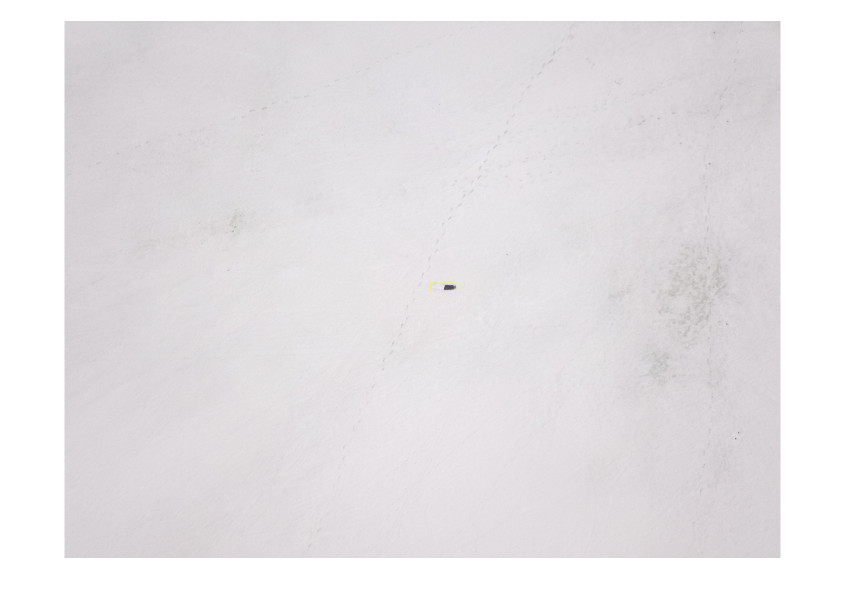

for i = 1:5
    data = read(trainingData);
    I = data{1};
    bbox = data{2};
    annotatedImage = insertShape(I,"Rectangle",bbox, LineWidth=5, ShapeColor="red");
    annotatedImage = imresize(annotatedImage,2);
    figure
    imshow(annotatedImage)
end

reset(trainingData);

## Create a YOLO v4 Object Detector Network

Specify the network input size to be used for training. 

inputSize = [416 416 3];

Specify the name of the object class to detect.

className = "annotations";

Use the [`estimateAnchorBoxes`](docid:vision_ref#mw_cba7b62d-6557-41e6-9e4d-73ec50667c6d) function to estimate anchor boxes based on the size of objects in the training data. To account for the resizing of the images prior to training, resize the training data for estimating anchor boxes. Use the `transform` function to preprocess the training data, then define the number of anchor boxes and estimate the anchor boxes. Resize the training data to the input size of the network by using the `preprocessData` helper function.

rng("default")
trainingDataForEstimation = transform(trainingData,@(data)preprocessData(data,inputSize));
numAnchors = 6;
[anchors,meanIoU] = estimateAnchorBoxes(trainingDataForEstimation,numAnchors);

Specify the `anchorBoxes` argument as the anchor boxes to use in all the detection heads. The anchor boxes are specified as a cell array of `[``M ``x 1]`, where M denotes the number of detection heads. Each detection head consists of a `[``N`` x 2]` matrix that is stored in the `anchors` argument, where `N` is the number of anchors to use. Specify the `anchorBoxes` for each detection head based on the feature map size. Use larger anchors at lower scale and smaller anchors at higher scale. To do so, sort anchors by area, in descending order, and assign the first three to the first detection head and the last three to the second detection head.

area = anchors(:, 1).*anchors(:,2);
[~,idx] = sort(area,"descend");

anchors = anchors(idx,:);
anchorBoxes = {anchors(1:3,:)
    anchors(4:6,:)};

For more information on choosing anchor boxes, see [Estimate Anchor Boxes from Training Data](docid:vision_ug#mw_671cb7a6-5a7a-4147-acf3-3e1fd7d3dfd7) (Computer Vision Toolbox™) and [Anchor Box Basics](docid:vision_ug#mw_f9f22f48-0ad0-4f37-8bc1-22a2046637f2).

Create the YOLO v4 object detector by using the `yolov4ObjectDetector` function. specify the name of the pretrained YOLO v4 detection network trained on COCO dataset. Specify the class name and the estimated anchor boxes.

detector = yolov4ObjectDetector("tiny-yolov4-coco",className,anchorBoxes,InputSize=inputSize);

## Perform Data Augmentation

Perform data augmentation to improve training accuracy. Use the `transform` function to apply custom data augmentations to the training data. The `augmentData` helper function applies the following augmentations to the input data:

- Color jitter augmentation in HSV space

- Random horizontal flip

- Random scaling by 10 percent

Note that data augmentation is not applied to the test and validation data. Ideally, test and validation data should be representative of the original data and is left unmodified for unbiased evaluation.

augmentedTrainingData = transform(trainingData,@augmentData);

Read and display samples of augmented training data.

augmentedData = cell(4,1);
for k = 1:4
    data = read(augmentedTrainingData);
    augmentedData{k} = insertShape(data{1},"rectangle",data{2});
    reset(augmentedTrainingData);
end
figure
montage(augmentedData,BorderSize=10)

## Specify Training Options

Use `trainingOptions` to specify network training options. Train the object detector using the Adam solver for 80 epochs with a constant learning rate 0.001. To get trained detector with lowest validation loss, set `OutputNetwork` to `"best-validation-loss"`. Set `ValidationData` to the validation data and `ValidationFrequency` to 1000. To validate the data more often, you can reduce the `ValidationFrequency` which also increases the training time. Use `ExecutionEnvironment` to determine what hardware resources will be used to train the network. The default value for `ExecutionEnvironment` is "`auto"`, which selects a GPU if it is available, and otherwise selects the CPU. Set `CheckpointPath` to a temporary location to enable the saving of partially trained detectors during the training process. If training is interrupted, for instance by a power outage or system failure, you can resume training from the saved checkpoint. 

options = trainingOptions("adam", ...
    GradientDecayFactor=0.9, ...
    SquaredGradientDecayFactor=0.999, ...
    InitialLearnRate=0.001, ...
    LearnRateSchedule="none", ...
    MiniBatchSize=4, ...
    L2Regularization=0.0005, ...
    MaxEpochs=15, ...
    DispatchInBackground=false, ...
    ResetInputNormalization=true, ...
    Shuffle="every-epoch", ...
    VerboseFrequency=20, ...
    ValidationFrequency=200, ...
    CheckpointPath=tempdir, ...
    ValidationData=validationData, ...
    OutputNetwork="best-validation-loss");

## Train YOLO v4 Object Detector

Use the `trainYOLOv4ObjectDetector` function to train YOLO v4 object detector. This example is run on an NVIDIA™ RTX A5000 with 24 GB of memory. Training this network took approximately 33 minutes using this setup. The training time will vary depending on the hardware you use. Instead of training the network, you can also use a pretrained YOLO v4 object detector in the Computer Vision Toolbox™.

Download the pretrained detector by using the `downloadPretrainedYOLOv4Detector` helper function. To train the detector on the augmented training data, set the `doTraining` value to `true`.

doTraining = true;
if doTraining       
    % Train the YOLO v4 detector.
    [detector,info] = trainYOLOv4ObjectDetector(augmentedTrainingData,detector,options);
    save("trainedDetector.mat", "detector");
else
    % Load pretrained detector for the example.
    loadedData = load("trainedDetector.mat");
    detector = loadedData.detector;
end

Run the detector on a test image.

I = imread("images/images/274.jpg");
[bboxes,scores,labels] = detect(detector,I);

Display the results.

I = insertObjectAnnotation(I,"rectangle",bboxes,scores);
figure
imshow(I)

## Evaluate Detector Using Test Set

Evaluate the trained object detector on a large set of images to measure the performance. Computer Vision Toolbox™ provides an object detector evaluation function ([`evaluateObjectDetection`](docid:vision_ref#mw_6aecf450-1718-4e91-b2cf-2972f639a177)) to measure common metrics such as average precision and log-average miss rate. For this example, use the average precision metric to evaluate performance.

Run the detector on all the test images. Set the detection threshold to a low value to detect as many objects as possible. This helps you evaluate the detector precision across the full range of recall values.

detectionResults = detect(detector,testData,Threshold=0.01);

Evaluate the object detector by using the [`evaluateObjectDetection`](docid:vision_ref#mw_6aecf450-1718-4e91-b2cf-2972f639a177) function on the test set results.

metrics = evaluateObjectDetection(detectionResults,testData);

The average precision provides a single number that incorporates the ability of the detector to make correct classifications (precision) and the ability of the detector to find all relevant objects (recall).

AP = averagePrecision(metrics);

The precision-recall (PR) curve highlights how precise a detector is at varying levels of recall. The ideal precision is 1 at all recall levels. The use of more data can help improve the average precision but might require more training time. Plot the PR curve.

[precision,recall] = precisionRecall(metrics,ClassName="annotations");

figure
plot(recall{:},precision{:})
xlabel("Recall")
ylabel("Precision")
grid on
title(sprintf("Average Precision = %.2f",AP))

## Supporting Functions

Helper function for performing data augmentation.

function data = augmentData(A)
% Apply random horizontal flipping, and random X/Y scaling. Boxes that get
% scaled outside the bounds are clipped if the overlap is above 0.25. Also,
% jitter image color.

data = cell(size(A));
for ii = 1:size(A,1)
    I = A{ii,1};
    bboxes = A{ii,2};
    labels = A{ii,3};
    sz = size(I);

    if numel(sz) == 3 && sz(3) == 3
        I = jitterColorHSV(I,...
            contrast=0.0,...
            Hue=0.1,...
            Saturation=0.2,...
            Brightness=0.2);
    end
    
    % Randomly flip image.
    tform = randomAffine2d(XReflection=true,Scale=[1 1.1]);
    rout = affineOutputView(sz,tform,BoundsStyle="centerOutput");
    I = imwarp(I,tform,OutputView=rout);
    
    % Apply same transform to boxes.
    [bboxes,indices] = bboxwarp(bboxes,tform,rout,OverlapThreshold=0.25);
    labels = labels(indices);
    
    % Return original data only when all boxes are removed by warping.
    if isempty(indices)
        data(ii,:) = A(ii,:);
    else
        data(ii,:) = {I,bboxes,labels};
    end
end
end

function data = preprocessData(data,targetSize)
% Resize the images and scale the pixels to between 0 and 1. Also scale the
% corresponding bounding boxes.

for ii = 1:size(data,1)
    I = data{ii,1};
    imgSize = size(I);
    
    bboxes = data{ii,2};

    I = im2single(imresize(I,targetSize(1:2)));
    scale = targetSize(1:2)./imgSize(1:2);
    bboxes = bboxresize(bboxes,scale);
    
    data(ii,1:2) = {I,bboxes};
end
end

Helper function for downloading the pretrained YOLO v4 object detector.

%function detector = downloadPretrainedYOLOv4Detector()
% Download a pretrained yolov4 detector.
%&if ~exist("yolov4TinyVehicleExample_24a.mat", "file")
 %   if ~exist("yolov4TinyVehicleExample_24a.zip", "file")
%        disp("Downloading pretrained detector...");
%        pretrainedURL = "https://ssd.mathworks.com/supportfiles/vision/data/yolov4TinyVehicleExample_24a.zip";
%        websave("yolov4TinyVehicleExample_24a.zip", pretrainedURL);
%    end
%    unzip("yolov4TinyVehicleExample_24a.zip");
%end
%pretrained = load("yolov4TinyVehicleExample_24a.mat");
%detector = pretrained.detector;
%end

*Copyright 2024 The MathWorks, Inc.*